# PARCISER - Projet 6.1 

## Génération de données simulées d'une SER

Le but est ici de se familiariser avec les données susceptibles d'être en sortie de l'analyseur de réseau, lors d'une série d'acquisition de la chambre anéchoïque de l'ENSTA.

La fonction gen_synth.m m'a été gracieusement donnée par le Dr. Comblet. Elle nécessite de poser plusieurs variables :

clear

xs = [-3 -1 1 1 1 1 3 5 5];
ys = [0 0 -3 -1 1 3 0 -2 2];  %Vu dans le poly de Mr Kenchaf

amps = 10.^[ones(1,length(xs))];
map = [xs'/10 ys'/5 amps'];  %Coordonnées des points brillants, en forme d'avion, + amplitude
map2 = [[0 0.5 1]'  [0 0 0]'  [10 10 10]'];
c0 = 3e8;

Il faudra vérifier quelle est l'unité des distances à fournir à map, pour que cela soit cohérent, en attendant je considèrerai que c'est le mètre. Se rappeler aussi que la résolution en distance dépend de la largeur de bande. Ne pas prendre des points brillants dont la distance est inférieure à la résolution, mais aussi une cible dont les dimensions sont supérieures à la fenêtre d'ambiguïté.

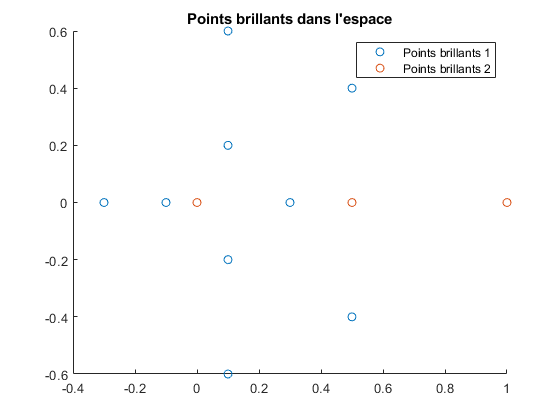

figure;
hold on
scatter(map(:,1),map(:,2),'DisplayName',"Points brillants 1")
scatter(map2(:,1),map2(:,2),'DisplayName',"Points brillants 2")
title("Points brillants dans l'espace")
legend
hold off

fmin = 8e9; fmax = 12e9; % fmin et fmax
th1 = -180; th2=180;  %angle min et max
nf = 200; nth = 6*360; %Nombre d'échantillons respectivement en angle, et en fréquence.
df = (fmax-fmin)/nf;
dth = (th2-th1)/nth;

freq = fmin:df:fmax-df;
angle = th1:dth:th2;

deltaR = c0/(2*(fmax-fmin));
Wd = c0/(2*df);
Wt = c0/(2*mean(freq)*dth*pi/180);

Ces variables sont posées en fonction des informations données par la page 15 de *Mesure de la SER*) 

Voyons ce que nous pouvons en faire.

sigc = gen_synth(map,fmin,fmax,nf,th1,th2,nth);  %Gpuarray() permet de faire les calculs sur le GPU, plus rapide.
sigc2 = gen_synth(map2,fmin,fmax,nf,th1,th2,nth);

sigc est une matrice de nf lignes, et nth colonnes.

Représentons la : 

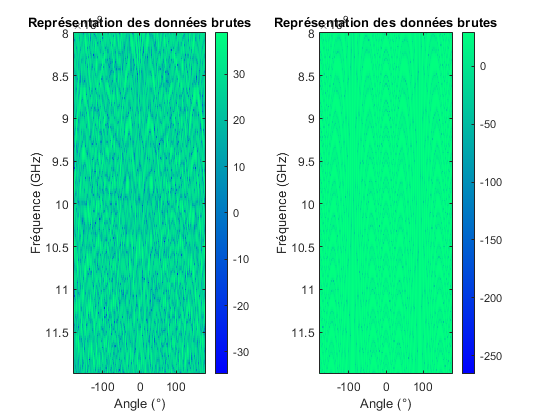

figure
subplot(1,2,1)
imagesc(angle,freq,20*log10(abs(sigc)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter
colorbar
title('Représentation des données brutes')
xlabel('Angle (°)')
ylabel('Fréquence (GHz)')
subplot(1,2,2)
imagesc(angle,freq,20*log10(abs(sigc2)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter
colorbar
title('Représentation des données brutes')
xlabel('Angle (°)')
ylabel('Fréquence (GHz)')

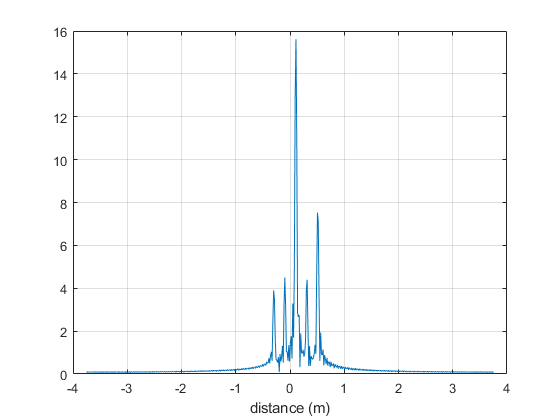

pro_dist=fftshift(ifft(sigc(:,1),512));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist)); %
figure;plot(distance,abs(pro_dist),'DisplayName',"sigc");xlabel("distance (m)");ylabel("");hold on; grid on

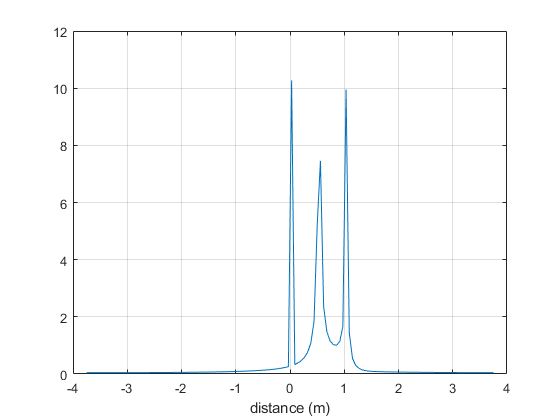

pro_dist2=fftshift(ifft(sigc2(:,1),128));  %Lorsque la cible est à -180°
distance=linspace(-Wd/2,Wd/2,length(pro_dist2)); %
figure;plot(distance,abs(pro_dist2),'DisplayName',"Zero Padded");xlabel("distance (m)");ylabel("");hold on; grid on

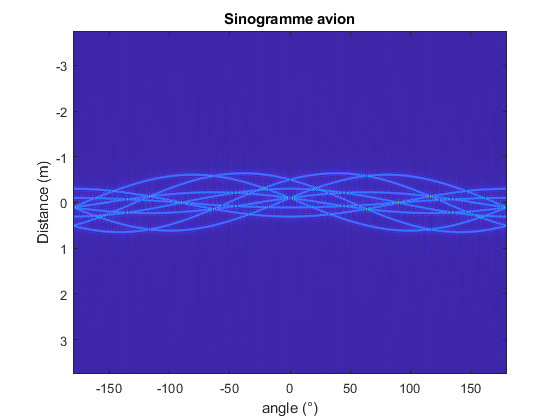

testsino=fftshift(ifft(sigc,1024));
sino=fftshift(ifft(sigc,1024),1);
figure;imagesc(angle,distance,abs(sino));xlabel("angle (°)"); ylabel("Distance (m)")
title("Sinogramme avion")

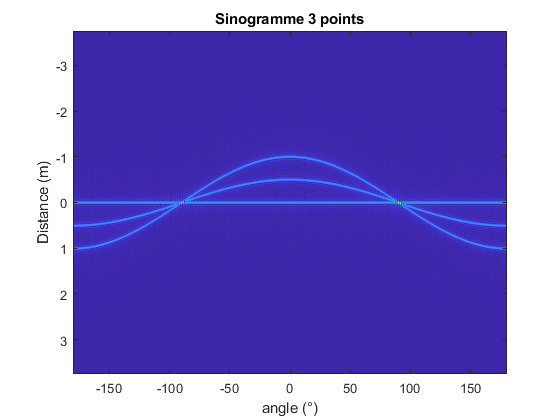

sino2=fftshift(ifft(sigc2,1024),1);
figure;imagesc(angle,distance,abs(sino2));xlabel("angle (°)"); ylabel("Distance (m)"); title("Sinogramme 3 points")

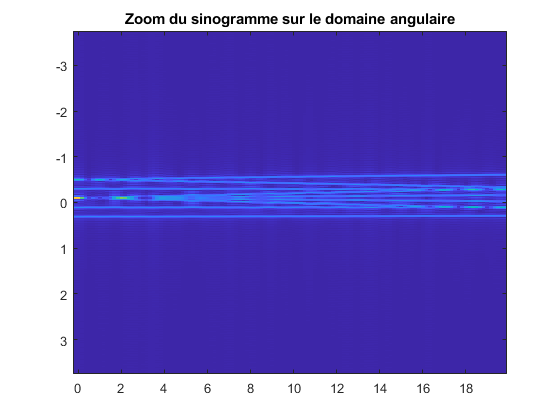

angle_debut = 180;
angle_fin = 200;
indice_debut = ceil(angle_debut*nth/360);
indice_fin = ceil(angle_fin*nth/360);
angles = indice_debut:indice_fin;
distanceT=linspace(-Wt/2,Wt/2,1024);
zoom = sino(:,angles);

figure
imagesc(angle(angles),distance,abs(zoom))
title("Zoom du sinogramme sur le domaine angulaire")

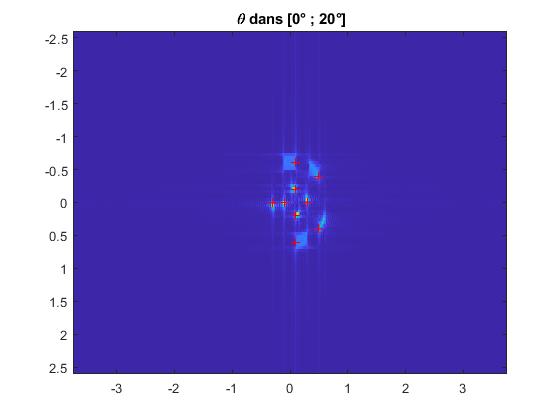

image = fftshift(fft(zoom,[],2),2);
figure
imagesc(distance,distanceT,fliplr(abs(image')))
title(" \theta dans [0° ; 20°]")
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red')

Nous voyons que l'avion apparait, mais que ça bave ! 

Petit test de rien du tout 

PSF = sinc .. Peut être qu'on aurait pu améliorer l'image avec Wiener deconv.. 

sinca = sinc(2*pi*mean(freq) *(-1:0.1:1));

sincb = sinc(2*pi*mean(freq) *(-1:0.1:1));

filt = meshgrid(sinca,sincb)

filt =     0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000   -0.0000   -0.0000   -0.0000   -0.000

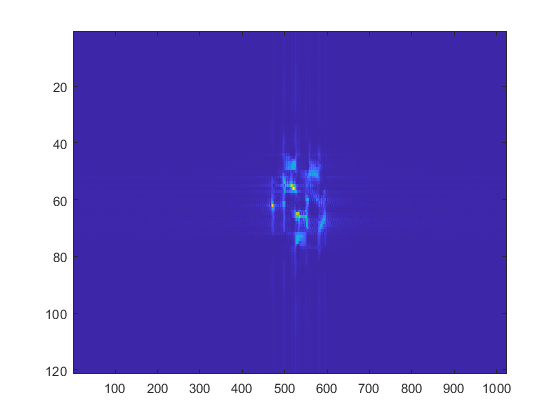

wnr2 = deconvlucy(fliplr(abs(image')),filt,5);
figure
imagesc(wnr2)

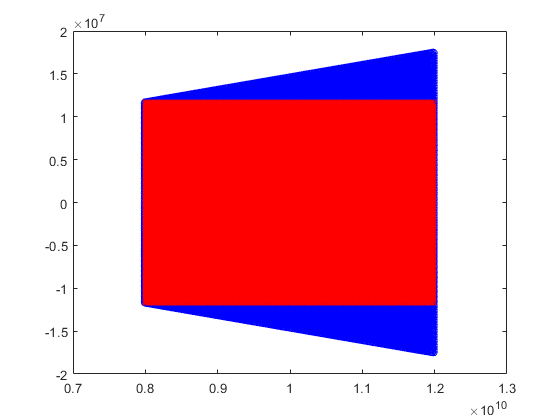

%coord cartesien
distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
f1=min(freq);f2=max(freq);
t1=-dth/2;t2=+dth/2;
fx=linspace(f1,f2,length(freq));
fy=linspace(t1,t2,length(distanceT))*pi/180;
[xi,yi]=meshgrid(fx,fy);
%coord polaire
xip=xi.*cos(yi);
yip=xi.*sin(yi);
figure;plot(xip,yip,'ob');hold on

distanceT=linspace(-Wt/2,Wt/2,(indice_fin-indice_debut+1));
yic=linspace(yip(1,1),yip(length(distanceT),1),length(distanceT));
xifin=sqrt(fx(1,end)^2-yic(1,end)^2);
xic=linspace(f1,xifin,length(freq));
[fx,fy]=meshgrid(xic,yic);
plot(fx,fy,'xr');xlim([fmin-1e9 fmax+1e9])

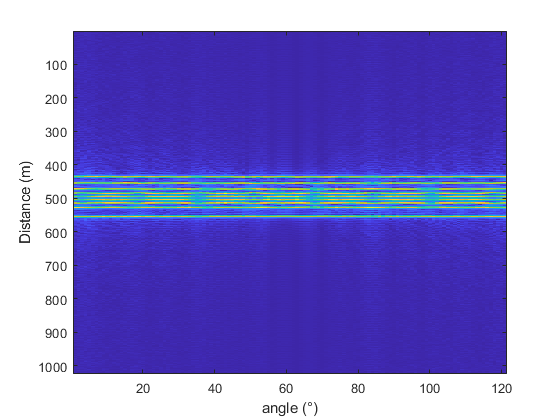

data=sigc(:,indice_debut:indice_fin);
datac=griddata(xip.',yip.',data,fx.',fy.','nearest');
sino3=fftshift(ifft(datac,1024),1);
figure;imagesc(abs(sino3));xlabel("angle (°)"); ylabel("Distance (m)")

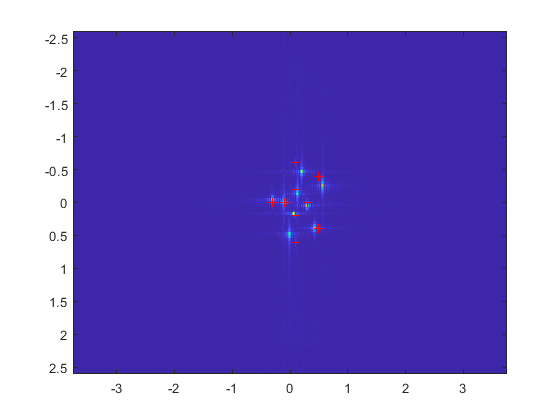

isar2 = fftshift(fft(sino3,[],2),2);
figure;imagesc(distance,distanceT,rot90(abs(isar2'),2));  %Je ne sais pas pourquoi faut que je fliplr :o
hold on;
plot(map(:,1),map(:,2),'+',"Color", 'red')

Ici, ça bave moins, mais je ne sais pas pourquoi j'ai du mettre rot90... 

Nous avons déjà un premier résultat. Essayons maintenant d'implémenter SPRITE petit à petit. 

Déjà, SPRITE se voulant parcimonieuse, il faut exprimer notre problème sous la forme suivante : $\sigma$ = **H*****a** + **n**

$\sigma$ correspond aux données de la chambre anéchoïque (il faudra peut-être la flatten) 

Dans le document "SPRITE : A New Sparse Approach for 3D High Resolution RCS Imaging", il est précisé que si l'on a nos données sur une grille cartésienne régulière (ce qui est le cas, avec la variable datac), alors **H **peut s'écrire :

H = $\alpha$ * $sqrt(N)$ * $\delta_\psi$ * $S$ * $F$ * $\delta_\phi$  

Mais, quelles sont les valeurs correspondantes ? 

alpha = 1 pour commencer, parce qu'après tout... pourquoi pas . 

N, j'ai le choix : nth, nf, nfft,.. 

Après tout, alpha et N sont juste des coeffs multiplicateurs, ça ne devrait pas non plus tout niquer si c'est égal à 1.

S est la matrice de sous-échantillonage. On va dire que c'est la matrice unité :) 

Le plus important, ici, c'est F. Il me semble que c'est la matrice de Wandermonde-Fourier.

F = zeros(size(datac));
N = 200*121;
for i=1:200
    for j=1:121
        F(i,j) = exp(-2*1j*pi*(i-1)*(j-1)/N);
    end
end


ADMM 

Alors... l'algorithme est expliqué dans le document. Seul "problème", c'est une plaie à décrypter. Il y a énormément de matrices différentes. Autant je peux deviner que le modèle utilisé, c'est la matrice de Wandermonde-Fourier, autant le reste faut vraiment que je me plonge dedans. 

Il doit certainement y avoir des simplifications, étant donné que je jarte une dimension..

Je viens de me rendre compte qu'il y a un truc qui s'appelle CVX, qui fait de l'optimisation. Peut-être que je peux adapter un code pour faire l'ADMM. 